% E8.8
clear all;
syms s w t

% (a)
Ts = 100*(s - 1)/(s^2 + 25*s + 100);

[n_ts0, d_ts0] = numden(Ts);
n0 = abs(solve(n_ts0 == 0,s));
d0 = abs(solve(d_ts0 == 0,s))';
w0 = [n0 d0];

for c = 1:size(w0,2)
    fprintf("T(s)의 절점주파수 : %.2f \n", w0(c))
end

T(s)의 절점주파수 : 1.00 
T(s)의 절점주파수 : 20.00 
T(s)의 절점주파수 : 5.00 


Ts_1 = 100*(s + 1)/(s^2 + 25*s + 100);

[n_ts1, d_ts1] = numden(Ts_1);
n1 = abs(solve(n_ts1 == 0,s));
d1 = abs(solve(d_ts1 == 0,s))';
w1 = [n1 d1];

for c = 1:size(w1,2)
    fprintf("T1(s)의 절점주파수 : %.2f \n", w1(c))
end

T1(s)의 절점주파수 : 1.00 
T1(s)의 절점주파수 : 20.00 
T1(s)의 절점주파수 : 5.00 


% (b)
num_ts0 = sym2poly(n_ts0);
den_ts0 = sym2poly(d_ts0);
sys_ts0 = tf(num_ts0, den_ts0);

[pro, deg, wout] = bode(sys_ts0);
slope_loww = 20*(log10(pro(:,:,2)) - log10(pro(:,:,1)))/(log10(wout(2)) - log10(wout(1)));
fprintf("T(s)의 낮은 주파수에서 기울기 : %4.0f [dB/decade]", slope_loww)

T(s)의 낮은 주파수에서 기울기 :    0 [dB/decade]

slope_highw = 20*(log10(pro(:,:,end)) - log10(pro(:,:,end-1)))/(log10(wout(end)) - log10(wout(end-1)));
fprintf("T(s)의 높은 주파수에서 기울기 : %4.0f [dB/decade]", slope_highw)

T(s)의 높은 주파수에서 기울기 :  -20 [dB/decade]


num_ts1 = sym2poly(n_ts1);
den_ts1 = sym2poly(d_ts1);
sys_ts1 = tf(num_ts1, den_ts1);

[pro, deg, wout] = bode(sys_ts1);
slope_loww = 20*(log10(pro(:,:,2)) - log10(pro(:,:,1)))/(log10(wout(2)) - log10(wout(1)));
fprintf("T1(s)의 낮은 주파수에서 기울기 : %4.0f [dB/decade]", slope_loww)

T1(s)의 낮은 주파수에서 기울기 :    0 [dB/decade]

slope_highw = 20*(log10(pro(:,:,end)) - log10(pro(:,:,end-1)))/(log10(wout(end)) - log10(wout(end-1)));
fprintf("T1(s)의 높은 주파수에서 기울기 : %4.0f [dB/decade]", slope_highw)

T1(s)의 높은 주파수에서 기울기 :  -20 [dB/decade]

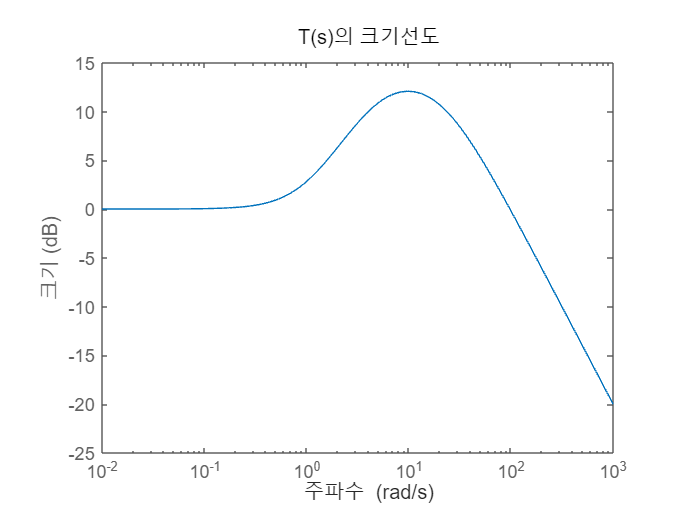

% (c)
bodemag(sys_ts0)
title("T(s)의 크기선도")

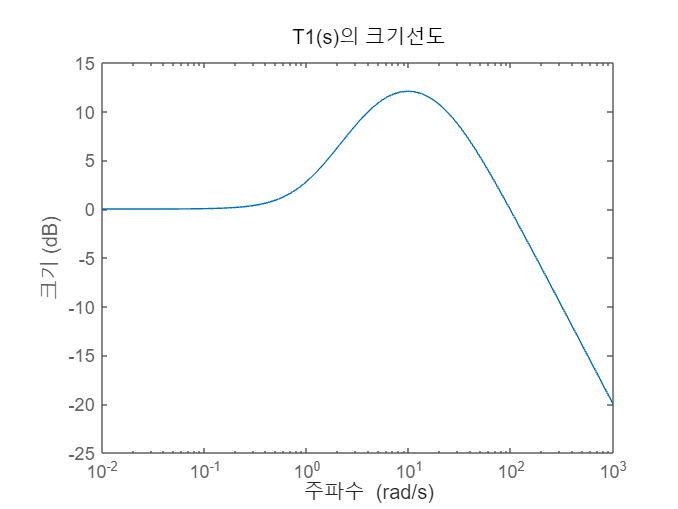

bodemag(sys_ts1)
title("T1(s)의 크기선도")

% 같은 모양이다.